clear all
clf
mu = 0.0010014; %dynamisk viscusitet
rho = 1000; %kg/m^3
d = 0.1; %m
Re = 100;
R = 0.05;


U = Re * mu / (rho * d)

U =                  0.0010014


format longg
% Define the filename and sheetname
filename = 'CFD_Data.xlsx';
sheetname = 'Plot Data';

% Import data from Excel file
[numericData, textData, rawData] = xlsread(filename, sheetname);

% Extract the desired range of data
% rowRange = 5:size(rawData, 1);
% colRange = [2, 3, 5, 6, 8, 9]; % Columns B, C, E, F, H, I

% Extract numeric data from specified range
% numericData = cell2mat(rawData(rowRange, colRange))

v_mesh_3 = numericData(:,2);

v_mesh_5 = numericData(:,5);
v_mesh_7 = numericData(:,8);

forskel_57 = max(v_mesh_5)/max(v_mesh_7)

forskel_57 =          0.986203104239441


forskel_75 = max(v_mesh_7)/max(v_mesh_5)

forskel_75 =           1.01398991313376


filename = 'Velocity.xlsx';
sheetname = 'Plot Data';

syms u(y) y

% Import data from Excel file
[numericData, textData, rawData] = xlsread(filename, sheetname);
Y = numericData(:,1);
u_sw = numericData(:,2);
U = 0.0010;
mu = 0.0010014;
R = 0.050; %mm radius

u_sol = 1/(4*mu) * 8*mu * U / R^2 .* (R^2 - Y.^2);

procent_afvigelse = max(u_sol)/max(u_sw)

procent_afvigelse =           1.02822374411616


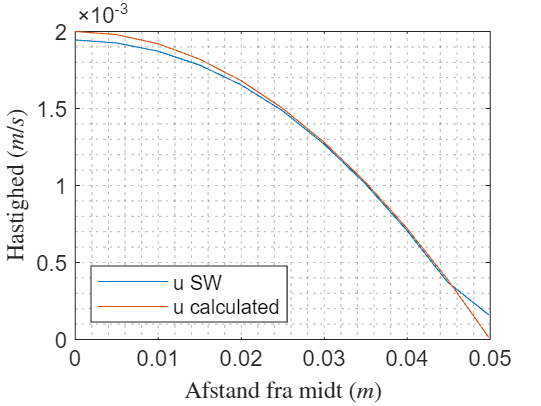


plot(Y, u_sw, 'DisplayName','u SW')
hold on
plot(Y, u_sol, 'DisplayName','u calculated')
xlabel('Afstand fra midt $(m)$', 'Interpreter','latex')
ylabel('Hastighed $(m/s)$', 'Interpreter','latex')
grid('minor')
legend('Location','southwest')
hold off

filename = 'total_pressure.xlsx';
sheetname = 'Plot Data';
syms x
P_atm = 101325;

% Import data from Excel file
[PressureData, textData, rawData] = xlsread(filename, sheetname);
Y = PressureData(:,1);
P_SW = PressureData(:,2);
% Y2 = Y;
% Y2(end +1) = 0.495;
[VelocityData, textData, rawData] = xlsread('Velocity_axial.xlsx', sheetname);
U_ax = VelocityData(:,2);

% U = flip(U_ax);
U = linspace(0.001, 0.001, 11)';

% P_start = P_atm;
P_cal = [];
for i = 1:length(Y)
    if i == 1
        P = P_atm;
    else
        P = P_start + (8.*mu.*U(i)./R^2) .* (Y(2)-Y(1));
    end
    P_cal(i) = P;
    P_start = P_cal(end);
end
P_cal = flip(P_cal)

P_cal =           101325.001442016          101325.001297814          101325.001153613          101325.001009411           101325.00086521          101325.000721008          101325.000576806          101325.000432605          101325.000288403          101325.000144202                    101325



dP = P_cal - P_atm;%(8.*mu.*U./R^2);


dP_SW = P_SW - P_atm;

procent_afvigelse = (mean(P) - mean(P_SW))/mean(P)

procent_afvigelse =       5.79121739898534e-09


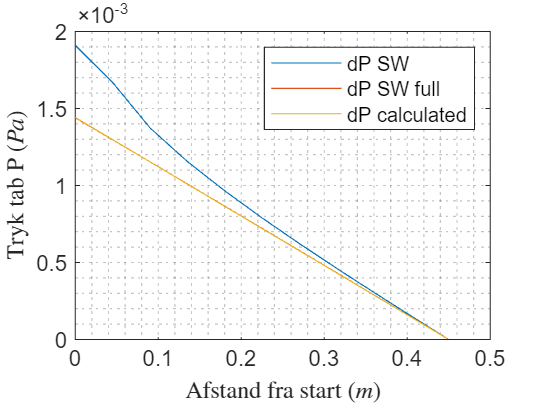


filename = 'Pressure.xlsx';
sheetname = 'Plot Data';

% Import data from Excel file
[PressureData, textData, rawData] = xlsread(filename, sheetname);
P_SW_full = PressureData(:,2);
Y2 = Y;
Y2(end +1) = 0.5;

dP_SW_full = P_SW_full - P_atm;

procent_afvigelse = (mean(P) - mean(P_SW_full))/mean(P);


plot(Y, dP_SW, 'DisplayName','dP SW')
hold on
plot(Y, dP_SW_full, 'DisplayName','dP SW full')
plot(Y, dP, 'DisplayName','dP calculated')
xlabel('Afstand fra start $(m)$', 'Interpreter','latex')
ylabel('Tryk tab P $(Pa)$', 'Interpreter','latex')
grid('minor')
legend('Location','northeast')
hold off

filename = 'Pressure_full_turb.xlsx';
sheetname = 'Plot Data';
syms x
P_atm = 101325;

% Import data from Excel file
[PressureData, textData, rawData] = xlsread(filename, sheetname);
Y_turb = PressureData(:,1);
P_SW_turb = PressureData(:,2);

d = 0.1; %m
L = 0.450; %m
rho = 1000; %kg/m^3
f = 0.316/Re^0.25

f =         0.0999279740613208


U= 0.001;
% U = linspace(0.001, 0.001, 25)';
% delta_P = f * L / d * (rho * U.^2)/2

% f*1000

P_cal_turb = [];
for i = 1:length(Y_turb)
    if i == 1
        P_turb = P_atm;
    else
        P_turb = P_start + f * L / d * (rho * U.^2)/2 .* (Y_turb(2)-Y_turb(1));
    end
    P_cal_turb(i) = P_turb;
    P_start = P_cal_turb(end);
end
P_cal_turb = flip(P_cal_turb)

P_cal_turb =           101325.000101177          101325.000096961          101325.000092745           101325.00008853          101325.000084314          101325.000080098          101325.000075883          101325.000071667          101325.000067451          101325.000063236           101325.00005902          101325.000054804          101325.000050588          101325.000046373          101325.000042157          101325.000037941          101325.000033726           101325.00002951          101325.000025294          101325.000021079          101325.000016863          101325.000012647          101325.000008431          101325.000004216                    101325



dP_turb = P_cal_turb - P_atm%(8.*mu.*U./R^2);

dP_turb =       0.000101176905445755      9.69612010521814e-05      9.27454966586083e-05      8.85297922650352e-05      8.43140878714621e-05       8.0098383477889e-05      7.58826790843159e-05      7.16669746907428e-05      6.74512702971697e-05      6.32355659035966e-05      5.90198615100235e-05      5.48041571164504e-05      5.05884527228773e-05      4.63727483293042e-05      4.21570439357311e-05      3.79413395421579e-05      3.37256351485848e-05      2.95099307550117e-05      2.52942263614386e-05      2.10785219678655e-05      1.68628175742924e-05      1.26471131807193e-05      8.43140878714621e-06      4.21570439357311e-06                         0




dP_SW_turb = P_SW_turb - P_atm

dP_SW_turb =        0.00136006499815267
       0.00130295800045133
       0.00125084900355432
       0.00119874000665732
        0.0011452820035629
       0.00109071499900892
       0.00103537600080017
       0.00097950900089927
      0.000923247003811412
      0.000866681002662517



procent_afvigelse = (mean(dP_turb) - mean(dP_SW_turb))/mean(dP_turb)

procent_afvigelse =          -12.6422856324279


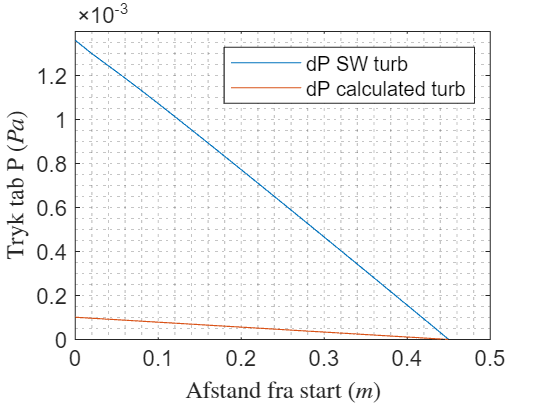


plot(Y_turb, dP_SW_turb, 'DisplayName','dP SW turb')
hold on
plot(Y_turb, dP_turb, 'DisplayName','dP calculated turb')
xlabel('Afstand fra start $(m)$', 'Interpreter','latex')
ylabel('Tryk tab P $(Pa)$', 'Interpreter','latex')
grid('minor')
legend('Location','northeast')
hold off